# Sample 7-2

## 幾何学処理

縮小処理

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Geometric image processing

Decimation

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 間引き率の設定

(Setting of downsampling factor)

- $M$: 間引き率 (downsampling factor) 

% Downsampling factor
dFactor = 2;

平均フィルタのインパルス応答 (Impulse response of averaging filter)

        
$$h[n]=\left\{\begin{array}{ll} \frac{1}{M} & 0\leq n\leq M-1 \\ 0 & \mathrm{otherwise} \end{array}\right.$$


- $\{h[n]\}_n$: インパルス応答 (Impulse response)

% Impulse response of averaging filter
h = ones(1,dFactor)/dFactor;

## フィルタ特性の表示

(Display of filter characteristics)

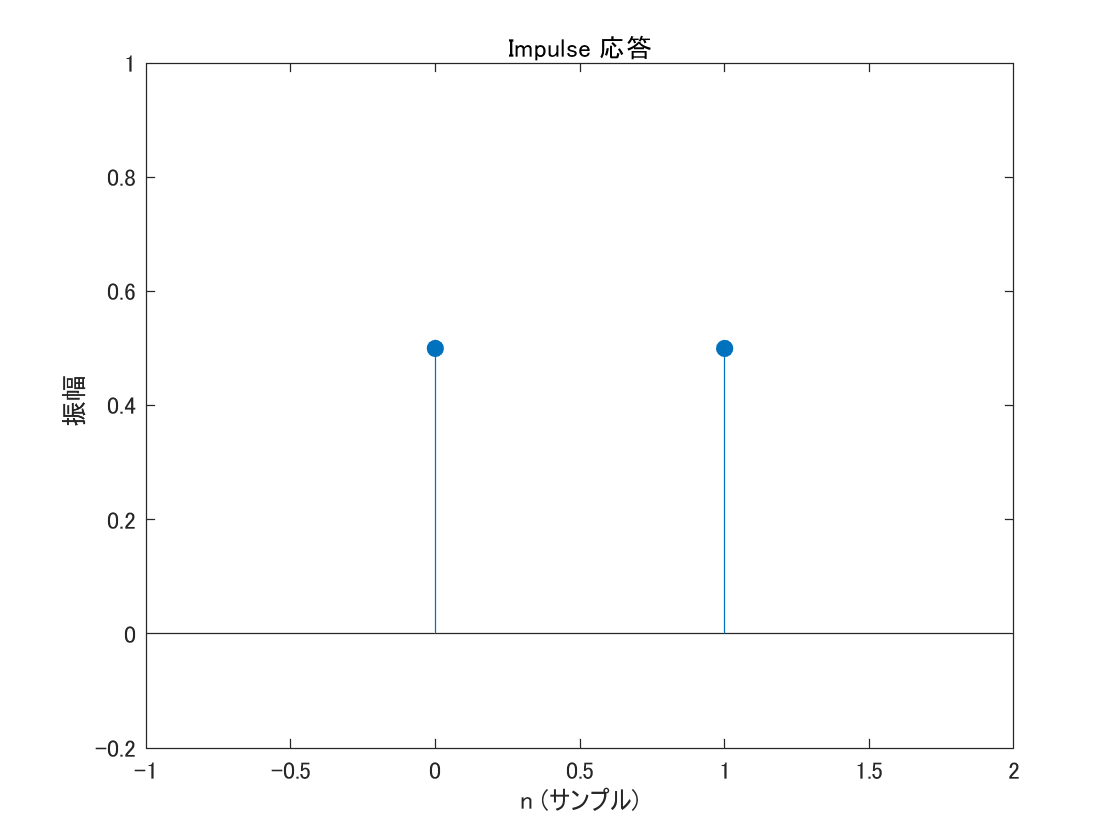

% Impulse response
figure(1)
impz(h)
ax = gca;
ax.XLim = [-1 length(h)];
ax.YLim = [-0.2 1];

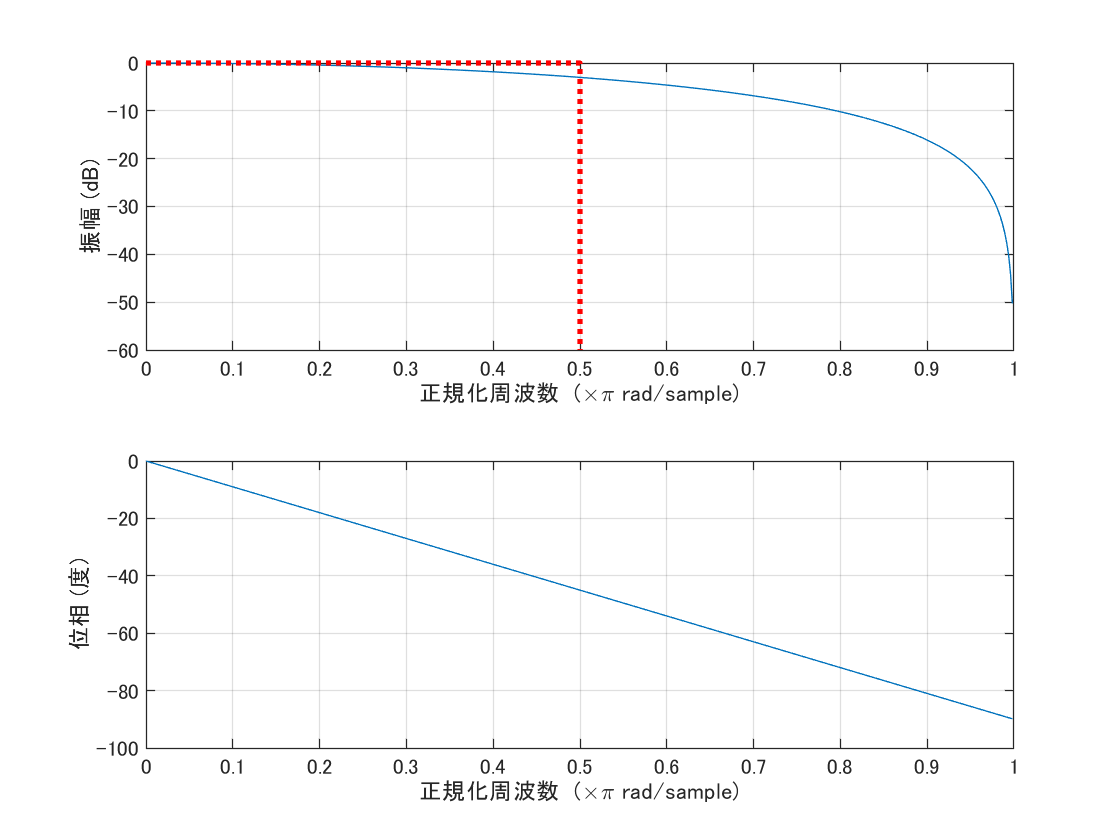


% Frequency response
figure(2)
freqz(h)
ax = gca;
hold on
line([0 1/dFactor 1/dFactor],[0 0 ax.YLim(1)],...
    'LineStyle',':','LineWidth',2,'Color','red');
hold off

### 画像への適用

(Application to images)

        
$$v[\mathbf{m}]=\sum_{\mathbf{k}\in\mathbb{Z}^2}h[\mathbf{k}]u[\mathbf{Mm}-\mathbf{k}]=\frac{1}{|\det\mathbf{M}|}\sum_{\mathbf{k}\in\mathcal{N}(\mathbf{M})}u[\mathbf{Mm}-\mathbf{k}]$$


        
$$h[\mathbf{n}]=\left\{\begin{array}{ll} \frac{1}{|\det\mathbf{M}|} & \mathbf{n}\in \mathcal{N}(\mathbf{M})\\ 0 & \mathrm{otherwise} \end{array}\right.$$


Note that if $\mathbf{M}=\mathrm{diag}(M,M)\Rightarrow |\det\mathbf{M}|=M^2$ and $\mathcal{N}(\mathbf{M})=\{0,1,\cdots,M-1\}^2$.

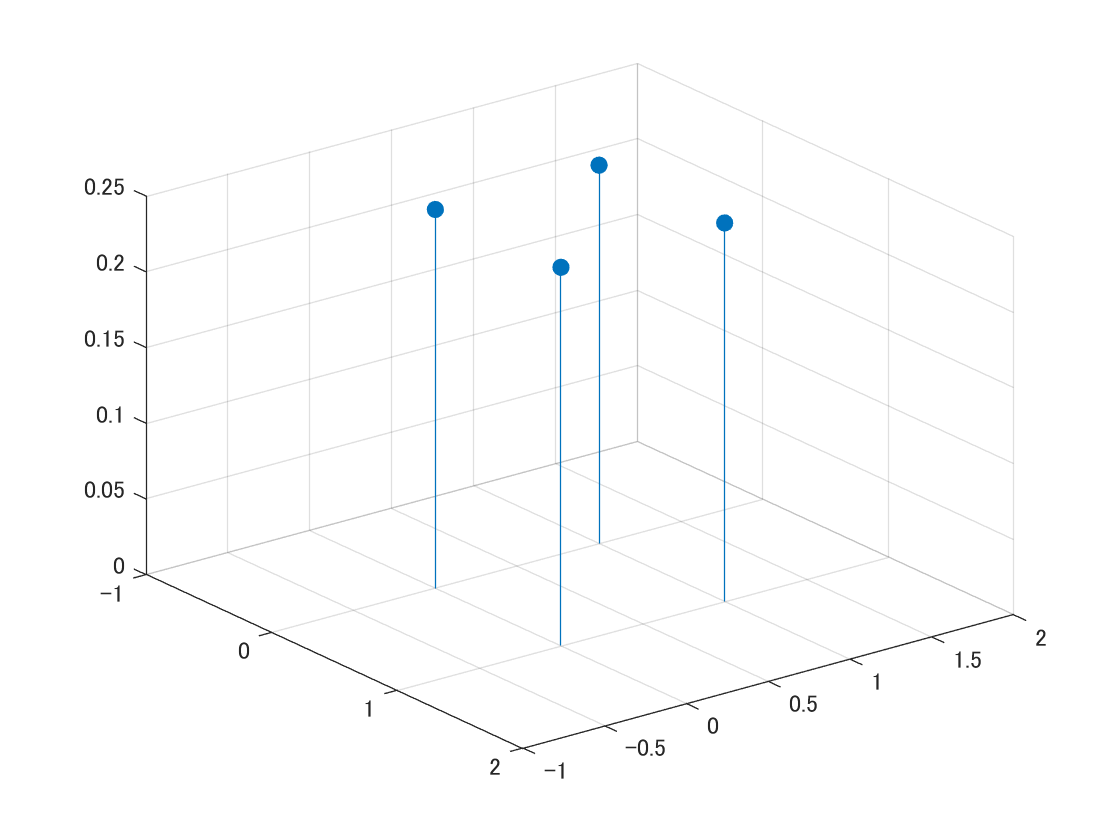

% Reading an image
u = imread('cameraman.tif');

% Generating the average filter
h = fspecial('average',dFactor);
figure(3)
stem3(0:(dFactor-1),0:dFactor-1,h,'filled')
axis ij
ax = gca;
ax.XLim = [-1 dFactor];
ax.YLim = [-1 dFactor];

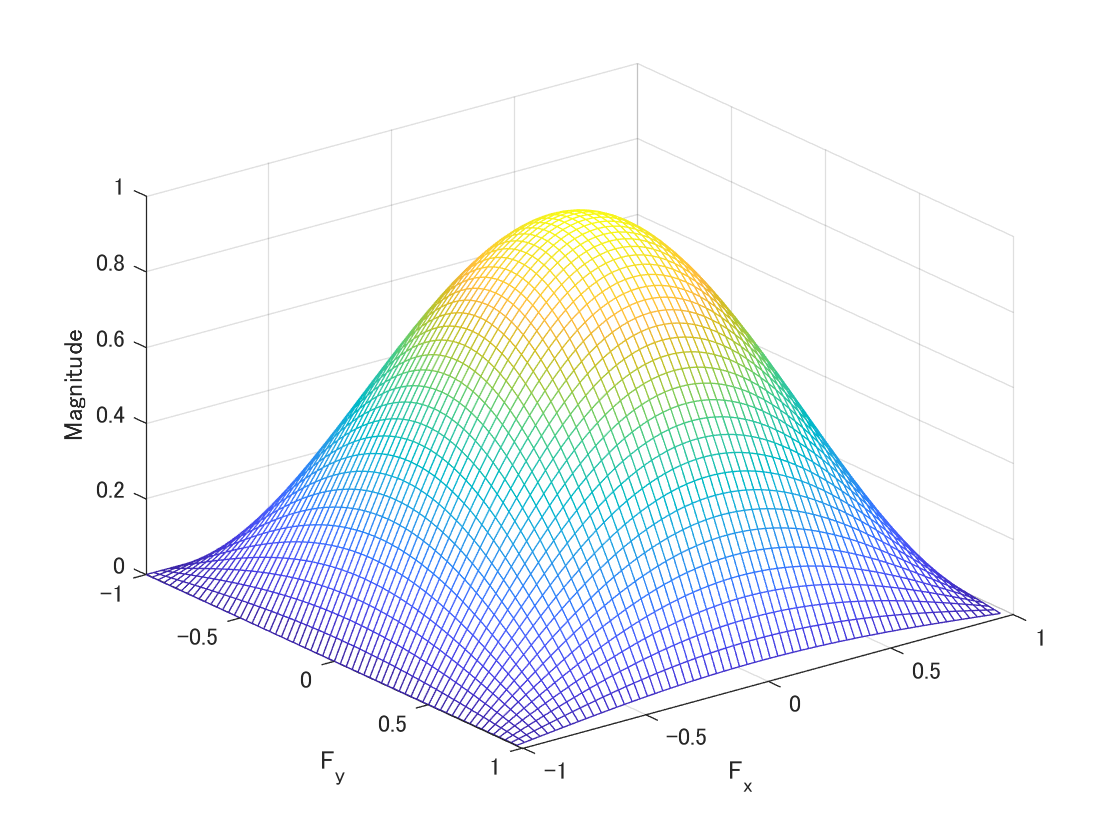

figure(4)
freqz2(h)
axis ij


% Bivariate downsampling function
downsample2 = @(x,n) ...
    shiftdim(downsample(...
    shiftdim(downsample(x,...
    n(1)),1),...
    n(2)),1);

% Box-averaging with filtering and downsampling
v = downsample2(imfilter(u,h,'conv'),dFactor*[1 1]);

% Box-averaging with IMRESIZE
y = imresize(u,1/dFactor,'box');


### 画像表示

(Display image)

原画像 (Original)

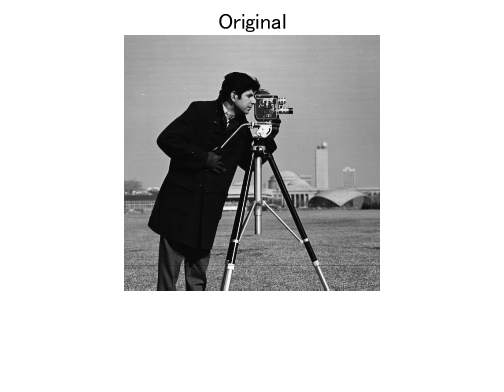

figure(5)
imshow(u)
title('Original')

縮小画像 (Decimated image)

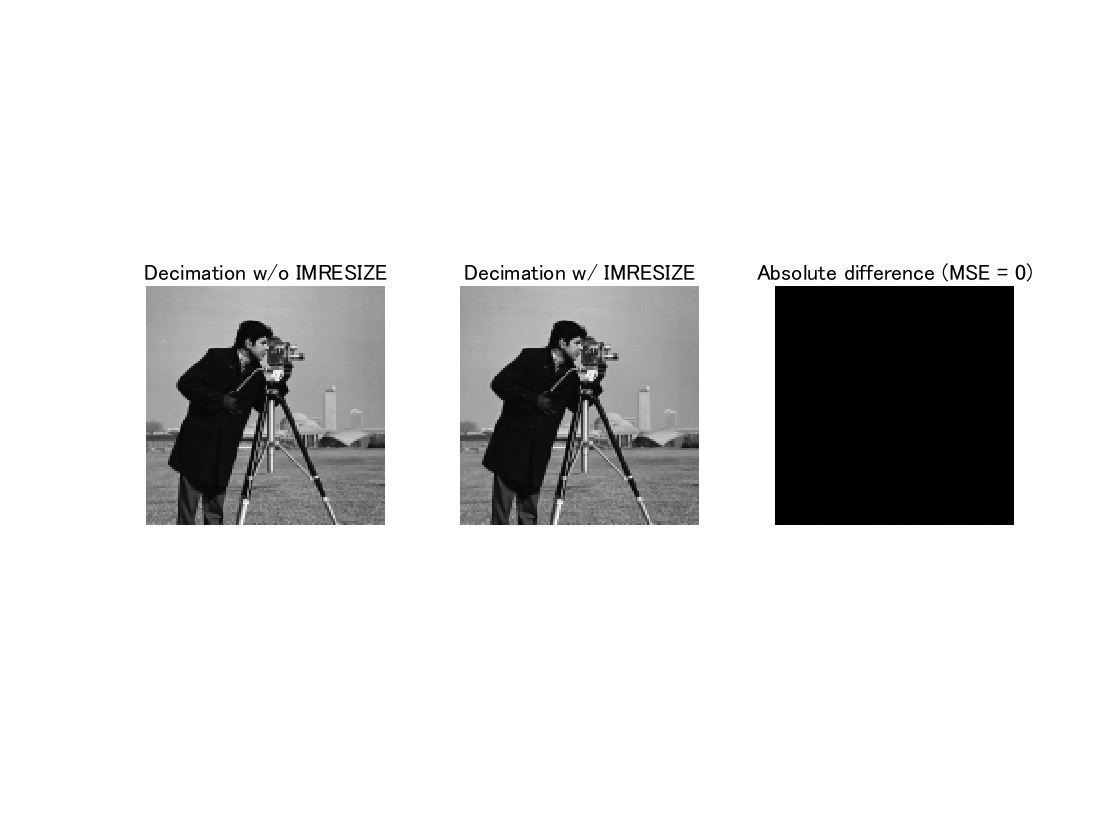

% Definition of MSE
mymse = @(x,y) sum((x-y).^2,'all')/numel(x);

% Display results
figure(6)
subplot(1,3,1)
imshow(v)
title('Decimation w/o IMRESIZE')
subplot(1,3,2)
imshow(y)
title('Decimation w/ IMRESIZE')
subplot(1,3,3)
imshow(imabsdiff(v,y))
title(['Absolute difference (MSE = ' num2str(mymse(v,y)) ')'])

© Copyright, Shogo MURAMATSU, All rights reserved.